%% Idea : Rather than simultaneous optimization of all three gears, assume

## Gearbox Targets

bending_safety_target = 1.2; % target safety factor that will be used to filter results from the sizing module
wear_safety_target = 1.1; % target safety factor that will be used to filter results from the sizing module
target_gr = 1.8;    % target gear ratio that will be used to filter results from the sizing module
gb_rad_lim = 130;   % maximum radial size the planetary assembly can have
if true % Use manual center distance option or maximum possible size for the given bearing and 
    target_center_dist = 38.1;
else
    target_center_dist = 1000*(wheelbearing.internalDiameter - planetPin.diameter)/2; %#ok<*UNRCH> 
    fprintf("Target Center Distance (mm): %.2f",target_center_dist);
end
makeIdenticalPlanets = true;

Definitions:

- Bending Safety Target - target bending safety factor that will be used to filter results from the sizing module

- Wear Safety Target - target wear safety factor that will be used to filter results from the sizing module;

- Target Gear Ratio - target gear ratio that will be used to filter results from the sizing module

- Manual/Maximum Possible - manually enter center distance or use the maxmim possible based on the given planet pin and bearing dimensions

- Target Center Distance - target center distance that will be used to filter results from the sizing module. Only valid when manual is selected

## Module Sweep Parameters

Defines an array of modules that will be swept across to find a gearbox size that satisifies the targets. Select exclude modules if there are certain modules in the range which are not available and enter those values into the dialog.

modulesStartVal = 0.5;
modulesIncrement = 0.05;
modulesEndVal = 1.5 ;
modules = modulesStartVal:modulesIncrement:modulesEndVal;
excludevals = 0;
if false
    openvar('excludevals');
end

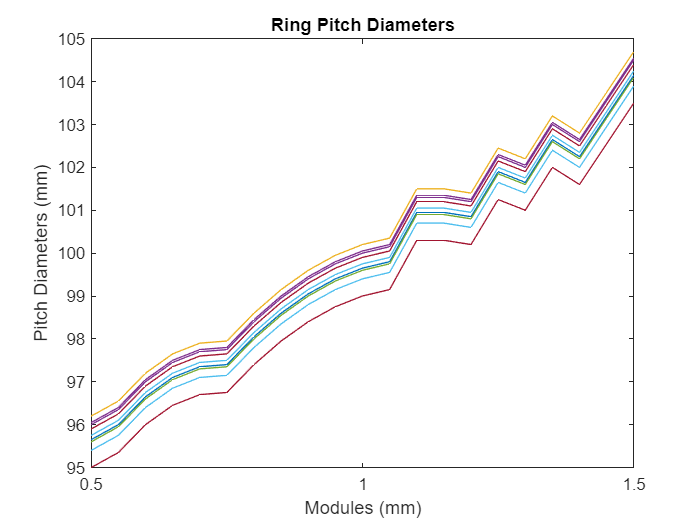

 

modules = modules(modules ~= excludevals); % removes excluded values from the sweep range

sunTeeths = zeros(size(modules)); % initializes empty vector for calculated minimum sun teeth

for i = 1:1:length(modules)
    [sunTeeths(i), rims(i)] = minSunTeeth(20,modules(i),sun,motor); % calculates the minimum number of teeth which avoids both undercut and rim thickness issues
    
end

if makeIdenticalPlanets
    sunTeeths(mod(sunTeeths,3) == 1) = sunTeeths(mod(sunTeeths,3) == 1) + 2;
    sunTeeths(mod(sunTeeths,3) == 2) = sunTeeths(mod(sunTeeths,3) == 2) + 1;
end

sunPitchDiameters = modules.*sunTeeths; % calculate pitch diameter from module and teeth count

% calculate number of planet teeth required to mesh with the sun for the
% given center distance. Floor is used to get an integer answer
planetTeeths = floor(2 * (target_center_dist - sunPitchDiameters/2)./modules); 

planetPitchDiameters = planetTeeths .* modules; % calculate actual pitch diameter
actual_center_dist = (sunPitchDiameters + planetPitchDiameters)/2; % calculate actual center distance (since floor was used it is no longer the target center distance as that would require a fractional tooth)

% Initialize empty structs and vectors for results
sun_safeties = struct('root',zeros(size(modules)),'flank',zeros(size(modules)));
planet_safeties = struct('root',zeros(size(modules)),'flank',zeros(size(modules)));

sunStages = struct([]);
ringStages = struct([]);
%trial_gb(1).sunStage = [];
%trial_gb(1).ringStage = [];
%trial_gb.ratio =[];

for i = 1:1:length(modules)
    % Build a trial sun struct which encapsulates important features of the
    % proposed sun gear
    trial_sun = generateGear(modules(i),sunTeeths(i),sun.facewidth,20, 1, 2.25, sun.hardness);

    % Build a trial planet struct which encapsulates important features of the
    % proposed sun stage of the planet gear
    trial_planetSunStage = generateGear(modules(i),planetTeeths(i),planet.sunStage.facewidth,20, 1, 2.25, planet.hardness);

    % Calculate safeties achieved by the meshing gears
    [sun_safety, planetSunStage_safety] = GearStress_PlanetSun(trial_sun,trial_planetSunStage,gearbox,motor,1 , 2.5, 50);

    % Record safeties to output vector
    sun_safeties.root(i) = sun_safety.root;
    sun_safeties.flank(i) = sun_safety.flank;
    trial_sun.root = sun_safety.root;
    trial_sun.flank = sun_safety.flank;
    trial_planetSunStage.root = planetSunStage_safety.root;
    trial_planetSunStage.flank = planetSunStage_safety.flank;

    planet_safeties.root(i) = planetSunStage_safety.root;
    planet_safeties.flank(i) = planetSunStage_safety.flank;

    sunStages(i).sun = trial_sun;
    sunStages(i).planet = trial_planetSunStage;
end

planetS2Teeths = zeros(size(modules));

for i = 1:1:length(modules)
    planetS2Teeths(i) = minTeeth(20,modules(i),planet.ringStage,16);
end

planetS2pitchDiameters = ones(length(planetS2Teeths)) .* planetS2Teeths' .* modules';
ringPitchDiameters = (planetS2pitchDiameters/2 + actual_center_dist) * 2;

ringTeeths = ringPitchDiameters ./ modules;
ringTeeths(floor(ringTeeths) ~= ringTeeths) = 0/0;

modsq = ones(length(modules)) .* modules';

for i = 1:1:length(modules)
    for j = 1:1:length(modules)
        % Build a trial sun struct which encapsulates important features of the
        % proposed sun gear
        trial_ring = generateGear(modsq(i,j),ringTeeths(i,j),ring.facewidth,20, 1, 2.25, ring.hardness);
    
        % Build a trial planet struct which encapsulates important features of the
        % proposed sun stage of the planet gear
        trial_planetRingStage = generateGear(modules(j),planetS2Teeths(j),planet.ringStage.facewidth,20, 1, 2.25, planet.hardness);
    
        ringStages(i,j).ring = trial_ring;
        ringStages(i,j).planet = trial_planetRingStage;

    end
end

counter = 1;
for i = 1:1:length(modules)
    for j = 1:1:length(modules)
        if ~(isnan(ringStages(i,j).ring.teethNum))
            
            trial_gb.sunStageModule(counter) = sunStages(i).sun.module;
            trial_gb.sunStageFacewidth(counter) = sunStages(i).sun.facewidth;
            trial_gb.sunRootSafety(counter) = sunStages(i).sun.root;
            trial_gb.sunFlankSafety(counter) = sunStages(i).sun.flank;
            trial_gb.sunPD(counter) = sunStages(i).sun.pitchDiameter;
            trial_gb.sunTeeth(counter) = sunStages(i).sun.teethNum;
            trial_gb.planetS1RootSafety(counter) = sunStages(i).planet.root;
            trial_gb.planetS1FlankSafety(counter) = sunStages(i).planet.flank;
            trial_gb.planetS1PD(counter) = sunStages(i).sun.pitchDiameter;
            trial_gb.planetS1Teeth(counter) = sunStages(i).planet.teethNum;
            trial_gb.sunStageContactRatio(counter) = getContactRatio(trial_gb.sunStageModule(counter),sunStages(i).sun.pressureAngle,trial_gb.sunTeeth(counter),trial_gb.planetS1Teeth(counter));
            trial_gb.centerDistance(counter) = actual_center_dist(i);

            trial_gb.ringStageModule(counter) = ringStages(i,j).ring.module;
            trial_gb.ringStageFacewidth(counter) = ringStages(i,j).ring.facewidth;
            trial_gb.ringPD(counter) = ringStages(i,j).ring.pitchDiameter;
            trial_gb.ringTeeth(counter) = ringStages(i,j).ring.teethNum;
            trial_gb.planetS2PD(counter) = ringStages(i,j).planet.pitchDiameter;
            trial_gb.planetS2Teeth(counter) = ringStages(i,j).planet.teethNum;
            trial_gb.ringStageContactRatio(counter) = getContactRatio(trial_gb.ringStageModule(counter),ringStages(i).ring.pressureAngle,trial_gb.ringTeeth(counter),trial_gb.planetS2Teeth(counter));

            %trial_gb.ratio(counter) = 1 + trial_gb.sunStage(counter).planet.teethNum * trial_gb.ringStage(counter).ring.teethNum / (trial_gb.sunStage(counter).sun.teethNum * trial_gb.ringStage(counter).planet.teethNum);
            counter = counter + 1;
        end
    end
end
trial_gb.ratio = 1 + trial_gb.planetS1Teeth .* trial_gb.ringTeeth ./ (trial_gb.sunTeeth .* trial_gb.planetS2Teeth);

plot(modules,ringPitchDiameters)
title("Ring Pitch Diameters")
ylabel("Pitch Diameters (mm)")
xlabel("Modules (mm)")

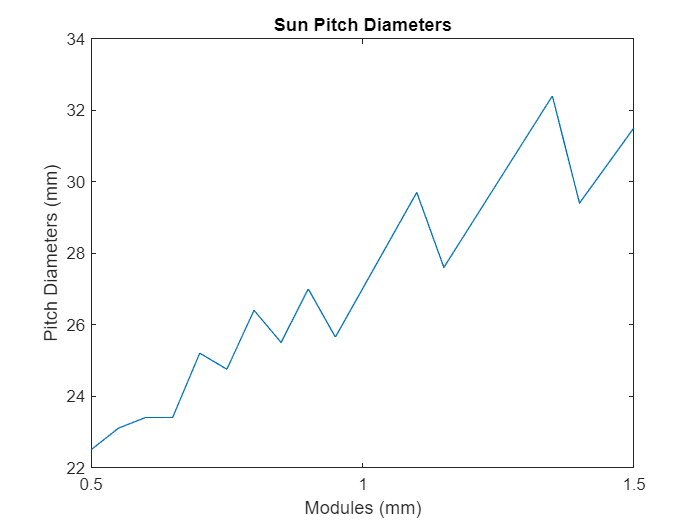


plot(modules,sunPitchDiameters)
title("Sun Pitch Diameters")
ylabel("Pitch Diameters (mm)")
xlabel("Modules (mm)")

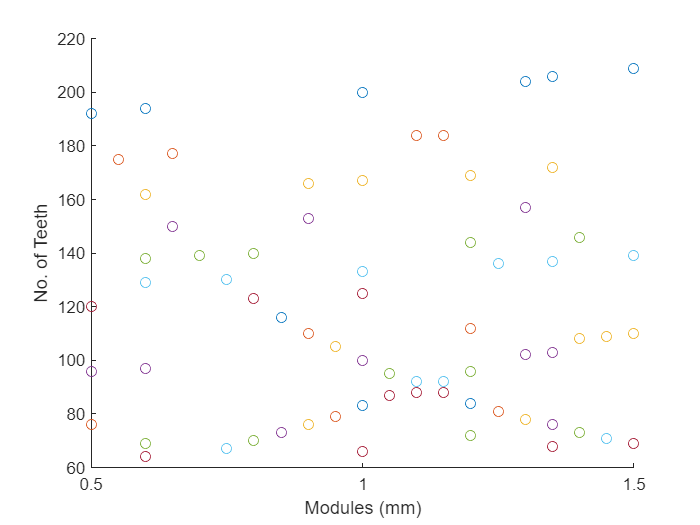


scatter(modules,ringTeeths)
ylabel("No. of Teeth")
xlabel("Modules (mm)")

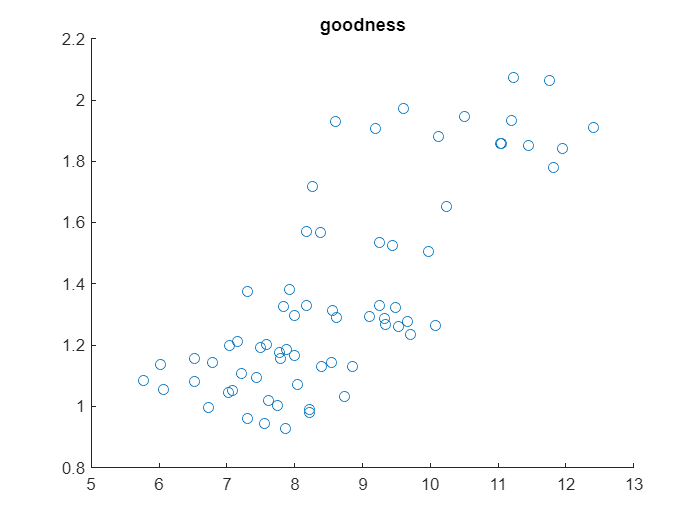



[trial_gb] = scoreGB(trial_gb,target_gr,1.2,1.2,gb_rad_lim);


scatter(trial_gb.ratio,trial_gb.score)
title("goodness")

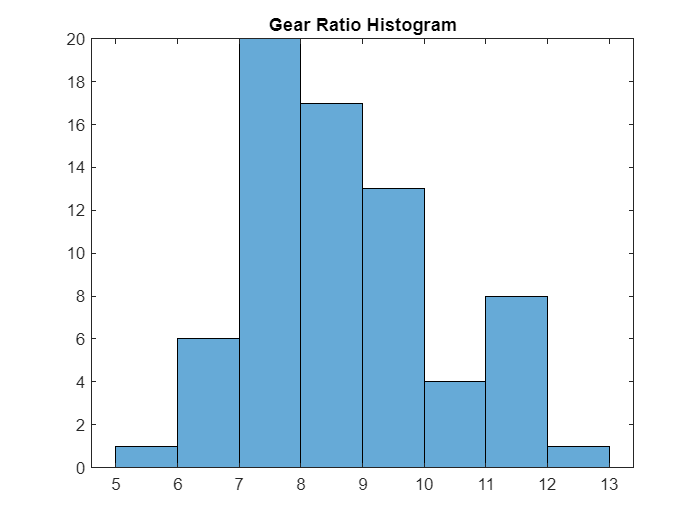


histogram(trial_gb.ratio)
title("Gear Ratio Histogram")

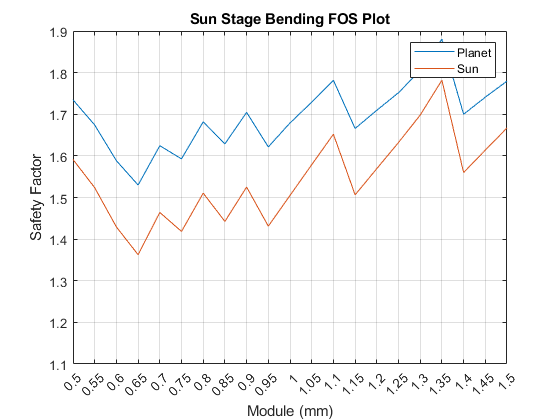


clear("output_table");

table_key = ["Ratio","Score","Sun Stage Module ","Sun Stage Facewidth", "Sun Stage Root Safety","Sun Stage Flank Safety", "Sun Pitch Diameter", "Sun Teeth","Planet S1 Root Safety","Planet S1 Flank Safety","Planet S1 Pitch Diameter","Planet S1 Teeth","Ring Module","Ring Stage Facewidth", "Ring PD","Ring Teeth","Planet S2 PD","Planet S2 Teeth"];
bbb = [trial_gb.ratio' trial_gb.score' trial_gb.sunStageModule' trial_gb.sunStageFacewidth' trial_gb.sunRootSafety' trial_gb.sunFlankSafety' trial_gb.sunPD' trial_gb.sunTeeth' trial_gb.planetS1RootSafety' trial_gb.planetS1FlankSafety' trial_gb.planetS1Teeth' trial_gb.ringStageModule' trial_gb.ringStageFacewidth' trial_gb.ringPD' trial_gb.planetS2PD' trial_gb.planetS2Teeth'];

writematrix(table_key,"new.xlsx")
writematrix(bbb,"new.xlsx","Range","A2")

f1 = figure;
    plot(modules,planet_safeties.root,modules,sun_safeties.root);
    title("Sun Stage Bending FOS Plot")
    ylabel("Safety Factor")
    xlabel("Module (mm)")
    yline(wear_safety_target)
    legend("Planet","Sun")
    xticks(modules)
    grid on 

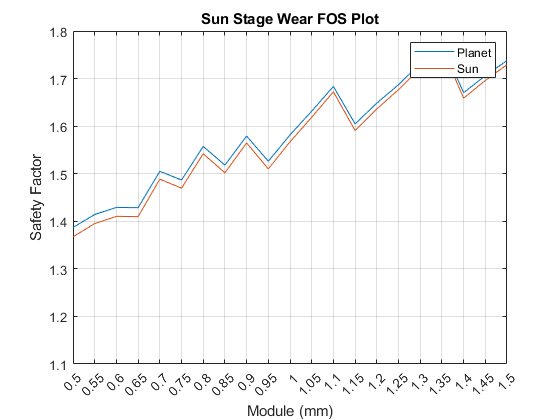


f2 = figure;
    plot(modules,planet_safeties.flank,modules,sun_safeties.flank);
    title("Sun Stage Wear FOS Plot")
    ylabel("Safety Factor")
    xlabel("Module (mm)")
    yline(wear_safety_target)
    legend("Planet","Sun")
    xticks(modules)
    grid on 

%{
% generate criteria used to evaluate solutions.
% Rows represent each unique criterion
% Columns represent the difference between the solution and target value
% achieved by that configuration for each row(criterion)
% To add new criteria, write an equation of output variables and target
% variables such that the criteria is satisfied when the output is greater
% than 0
pass_criteria = struct('margin',zeros(1,length(modules)));
pass_criteria.margin(1,:) = planetTeeths./sunTeeths - target_gr;
pass_criteria.margin(2,:) = sun_safeties.flank - wear_safety_target;
pass_criteria.margin(3,:) = gb_rad_lim - planetPitchDiameters+sunPitchDiameters/2;
pass_criteria.margin(4,:) = sun_safeties.root - bending_safety_target;

addendum_radii_pinion = modules + modules.*sunTeeths/2;
base_radii_pinion = cosd(20) * modules.*sunTeeths/2;
lpinion = sqrt(addendum_radii_pinion.^2-base_radii_pinion.^2);

addendum_radii_gear = modules + modules.* planetTeeths/2;
base_radii_gear = cosd(20) * modules.*planetTeeths/2;
lgear = sqrt(addendum_radii_gear.^2-base_radii_gear.^2);

cdist = modules.*(sunTeeths+planetTeeths)/2;

base_pitch = pi*modules;
pass_criteria.margin(5,:) = (lpinion+lgear-sind(20)*cdist)./base_pitch;

% values used to non dimensionalize the difference between each solutions
% parameters and the target parameters. This prevents criteria which use
% numerically high values from biasing the results


nonDimVector = [target_gr wear_safety_target gb_rad_lim bending_safety_target 1.2]';
pass_criteria.nonDimMargin = pass_criteria.margin ./nonDimVector;

% labels for each criteria which will be used to inform the user of
% which criteria the closest solution failed in the event that no solution
% satisfies all of them
pass_criteria.labels(1) = "Gear Ratio";
pass_criteria.labels(2) = "Sun Wear Safety";
pass_criteria.labels(3) = "Overall radius limit";
pass_criteria.labels(4) = "Sun Bending Safety";
pass_criteria.labels(5) = "Contact Ratio";

% essential margin contains only the margins of those criteria which will
% be used to exclude soltions. Here, gear ratio is not being used to
% exclude soltutions so it is removed from essential margin
essential_margin = pass_criteria.margin(2:end,:);

% filter solutions which did not pass essential criteria
pass_criteria.pass = sum(essential_margin > 0,1) == size(essential_margin,1);

% weight which when multiplied with non dimensionalized margin will be used to value the relative importance of each
% criteria
pass_criteria.weights = [1 1 1 1 1];
 
weighted_criteria = pass_criteria.weights * pass_criteria.nonDimMargin;

% extract the "goodness" or sum of weighted non dimensionalized values of
% solutions that passed from the larger array
reduced_weighted_criteria =  weighted_criteria(:,pass_criteria.pass);
reduced_modules = modules(pass_criteria.pass);

% clears the output table in case there are lingering values from a
% previous run
clear("output_table");

if ~isempty(reduced_modules) % condition if a solution is found
    
    % add goodness of valid solutions to output table and display
    %output_table.goodness =  reduced_weighted_criteria';
    %output_table.passed_modules =  reduced_modules';
    %disp(struct2table(output_table))
    
    plot(reduced_modules,reduced_weighted_criteria)
    title("Goodness")
    xlabel("Modules (mm)")
    ylabel("Goodness")

    % find the index of the best solution in the reduced vector consisting
    % of valid solutions only
    [~, reduced_best_index] = max(reduced_weighted_criteria);

    % find the same value in the larger array containing all the original
    % trial solutions
    best_index = reduced_modules(reduced_best_index) == modules;
    
    % calculate the effective internal diameter of the sun gear accounting
    % for the protrusion of the keyway ( these values should be 0 if using
    % a splined shaft
    effectiveInternalDiameter = 2 * sqrt((sun.internalDiameter / 2 + motor.keyProjHeight)^2 + (motor.keyWidth / 2)^2);
    
    % calculate the rim thickness of the sun gear for the best solution
    sun_rim = sunPitchDiameters(best_index)/2 - modules(best_index)*(sun.whole_depth_factor-sun.addendum_factor) - 1000*effectiveInternalDiameter/2;
    bratio = sun_rim ./ (sun.whole_depth_factor.* modules) 
    % output formatting
    fprintf(" \n \n \n \nBest Configuration:")
    fprintf("Module (mm): \t\t\t%.2f",modules(best_index))
    printFormatLine()
    fprintf(" \n \n")
    fprintf("Sun Gear:")
    printFormatLine()
    fprintf("Teeth: \t\t\t%d",sunTeeths(best_index))
    fprintf("Pitch Diameter (mm): \t%.2f",sunPitchDiameters(best_index))
    fprintf("Rim Thickness (mm): \t%.2f",sun_rim);
    fprintf(" \n \n \n \n")
    fprintf("Planet Gear:")
    printFormatLine()
    fprintf("Teeth: \t\t\t%d",planetTeeths(best_index))
    fprintf("Pitch Diameter (mm): \t%.2f",planetPitchDiameters(best_index))
    
    f1 =figure;
    plot(reduced_modules,planet_safeties.root(modules == reduced_modules),modules,sun_safeties.root(modules == reduced_modules));
    title("Bending FOS Plot")
    ylabel("Safety Factor")
    xlabel("Module (mm)")
    yline(bending_safety_target)
    legend("Planet","Sun")
    xticks(modules)
    grid on
    
    f2 = figure;
    plot(modules,planet_safeties.flank,modules,sun_safeties.flank);
    title("Wear FOS Plot")
    ylabel("Safety Factor")
    xlabel("Module (mm)")
    yline(wear_safety_target)
    legend("Planet","Sun")
    xticks(modules)
    grid on 
    
    f3 = figure;
    plot(modules,planetTeeths./sunTeeths)
    title("Highest Achieveable Gear Ratio")
    ylabel("Gear Ratio")
    xlabel("Module")
    yline(target_gr)
    xticks(modules)
    grid on

    f4 = figure;
    plot(modules,pass_criteria.margin(5,:))
    title("Contact Ratio")
    ylabel("Contact Ratio")
    xlabel("Module")
    xticks(modules)
    grid on
    
else % condition if not solution is found
    fprintf("No Solution Found")

    % find the index of the trial solution that satisified the most
    % criteria
    [~, closest_solution_index] = max(sum(pass_criteria.margin > 0,1)); 

    % find the criteria that the closest solution failed
    failed_criteria_index = find(pass_criteria.margin(:,closest_solution_index) <= 0);
    
    % append failed criteria and non dimensional margin of failure to the output table and display
    output_table.failed_criteria = pass_criteria.labels(failed_criteria_index)';
    output_table.relative_margin_of_failure = pass_criteria.margin(failed_criteria_index,closest_solution_index)';
    disp(struct2table(output_table))
end
%}

function [minTeeth, rim_thickness] = minSunTeeth(pressureAngle,module,sun,motor)
    backup_ratio = 1.2;
    deddendum_factor = sun.whole_depth_factor - sun.addendum_factor;
    tooth_height = sun.whole_depth_factor * module;
    rim_thickness = tooth_height * backup_ratio;
    %effectiveInternalDiameter = 2 * sqrt((sun.internalDiameter / 2 + motor.keyProjHeight)^2 + (motor.keyWidth / 2)^2);
    %pitchDiameter = 2 * (rim_thickness + deddendum_factor * module + 1000 * effectiveInternalDiameter / 2);
    pitchDiameter = 2 * (rim_thickness + deddendum_factor * module + 1000 * sun.internalDiameter / 2);
    minTeeth_rim = ceil(pitchDiameter / module);
    minTeeth_undercut = ceil(2 / (sind(pressureAngle))^2);
    minTeeth = max(minTeeth_rim,minTeeth_undercut);
end

function [minTeeth] = minTeeth(pressureAngle,module,gear,internalDiameter)
    backup_ratio = 1.2;
    deddendum_factor = gear.whole_depth_factor - gear.addendum_factor;
    tooth_height = gear.whole_depth_factor * module;
    rim_thickness = tooth_height * backup_ratio;
    pitchDiameter = 2 * (rim_thickness + deddendum_factor * module + internalDiameter / 2);
    minTeeth_rim = ceil(pitchDiameter / module);
    minTeeth_undercut = ceil(2 / (sind(pressureAngle))^2);
    minTeeth = max(minTeeth_rim,minTeeth_undercut);
end

function [gear] = generateGear(module,teeth,facewidth,pressureAngle, addendum_factor, whole_depth_factor,hardness)
    gear.module = module;
    gear.teethNum = teeth;
    gear.pitchDiameter = module * teeth;
    gear.facewidth = facewidth;
    gear.addendum = addendum_factor * module;
    gear.wholeDepth = whole_depth_factor * module;
    gear.deddendum = gear.wholeDepth - gear.addendum;
    gear.pressureAngle = pressureAngle;
    gear.hardness = hardness;
end

function[] = printFormatLine()
    fprintf("--------------------------------------")
end

function[array] = vectorize(structure,field)
    array = zeros(size(structure));
    for i = 1:1:length(structure)
        array(i) = getfield(structure(i),field);
    end
end
function[array] = nestedVectorize(structure,field,subfield)
    array = zeros(size(structure));
    for i = 1:1:length(structure)
        substruct = getfield(structure(i),field);
        array(i) = getfield(substruct,subfield);
    end
end

function[trial_gb] = scoreGB(trial_gb,target_gr,flank_safety,root_safety, gb_rad_lim)
    ndRatio = getWeightedScore(1,target_gr,trial_gb.ratio);
    ndSunRoot = getWeightedScore(10,root_safety,trial_gb.sunRootSafety);
    ndSunFlank= getWeightedScore(5,flank_safety,trial_gb.sunFlankSafety);
    trial_gb.size = trial_gb.planetS1PD+trial_gb.sunPD/2;
    trial_gb.score = sum([ndRatio; ndSunRoot; ndSunFlank]);
    trial_gb.score(trial_gb.size > gb_rad_lim) = 0;
end

function[score] = getWeightedScore(weight,target,value)
    score = weight * abs(target-value)/target;
    score = 1./score;
end